# MATH2089 Week 8

In this week's lab we'll examine statistical tests for comparing two different means. Let's suppose that we have two** independent** populations $P_{1}$ and $P_{2}$ with respective distribution functions $F_{1}$ and $F_{2}$. We assume that the means for $F_{1}$ and $F_{2}$ are respectively $\mu_{1}$ and $\mu_{2}$. We want to test if the two means are different. Let's collect two samples from each distribution: $X_{1},\dots,X_{n_{1}}\sim F_{1}$ and $Y_{1},\dots,Y_{n_{2}}\sim F_{2}$. Naturally the sample means $\overline{X}$ and $\overline{Y}$ are respective estimators for $\mu_{1}$ and $\mu_{2}$. If $F_{1}\equiv N(\mu_{1},\sigma)$ and $F_{2}\equiv N(\mu_{2},\sigma)$, then $\overline{X}\sim N\left(\mu_{1},n^{-1/2}_{1}\sigma\right)$ and $\overline{Y}\sim N\left(\mu_{2},n^{-1/2}_{2}\sigma\right)$. It follows that

$\overline{X} - \overline{Y} \sim N\left(\mu_{1} - \mu_{2}, \sigma\sqrt{\frac{1}{n_{1}} + \frac{1}{n_{2}}}\right) \Rightarrow \frac{\overline{X} - \overline{Y} - \left(\mu_{1} - \mu_{2}\right)}{\sigma\sqrt{\frac{1}{n_{1}} + \frac{1}{n_{2}}}} \sim N(0,1)$.

Hence we have established a test statistic whose distribution is independent of the parameters—meaning we can perform a statistical test!

## Question one

The `fusiondat` dataset supplies log-times for two independent groups, one in which the subjects receive no prior information $(g = 1)$ and one in which the subjects received verbal and visual information beforehand $(g =2)$. We want to compare the mean log-time to fusion between the two groups. Let's start with importing the data, examining group-level descriptive statistics, and producing group-level boxplots.

fusion = readmatrix("data/fusiondat.txt"); 

treatment = fusion(:, 1);
logTime = fusion(:, 2);

% grpstats outputs function values according to group membership
% see help grpstats
[groupSize, groupMean, groupStD, groupVar] = grpstats(logTime, treatment, {'numel', 'mean', 'std', 'var'})

groupSize =     43
    35


groupMean =     1.8200
    1.3895


groupStD =     0.8137
    0.8178


groupVar =     0.6621
    0.6688


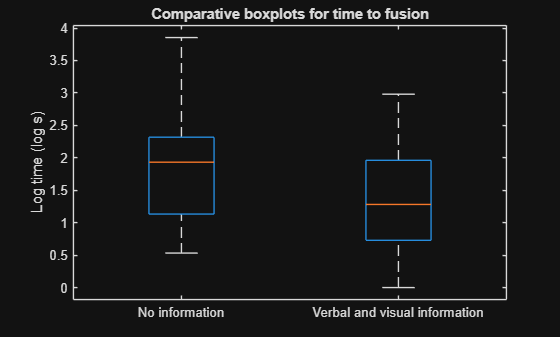

figure(1)
boxplot(logTime, treatment, "labels", ["No information", "Verbal and visual information"])
ylabel('Log time (log s)')
title("Comparative boxplots for time to fusion")

The sample means for the groups are $\overline{x} = 1.82$ and $\overline{y} \approx 1.39$. The difference $\overline{x} - \overline{y} = -0.4306$ is relatively large compared to the *pooled sample standard deviation*

$s_{p} = \sqrt{\frac{(n_{x}- 1)s^{2}_{x} + (n_{y} - 1)s^{2}_{y}}{(n_{x} + n_{y} - 2)}} = \sqrt{\frac{(43 - 1)\cdot0.8137^{2} + (35 - 1)\cdot0.8178^{2}}{43 + 35 - 2}}}$ = 0.8156.

The comparative boxplots corroborate this heuristic conclusion since they show a material differences shift in the average location between each data set. In particular, it appears that treatment group two—which received visual and verbal information prior—have a smaller time to fuse the images. 

In order to make a statistical comparison, we should apply a *two sample *$t$-*test* since we wish to compare the population means between two independent samples. 

We require the popultion variances to be equal in order to apply a two sample t-test. We can formally test equality of population variances through *Welch's* *test*, however, we can also apply the heuristic that $\sigma_{x} = \sigma_{y}$ if $\frac{1}{2}s_{x} \leq s_{y} \leq 2s_{x}$. The sample standard deviations $s_{x}$ and $s_{y}$ satisfy this heuristc, hence we shall assume equality of population variances.

Similarly to last week, we need the sample means $\overline{X}$ and $\overline{Y}$ to be Normally distributed. We can check this using a quantile plot.

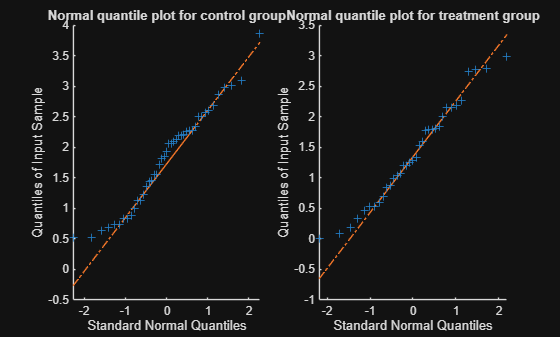

figure(2)
subplot(1,2,1)
qqplot(logTime(treatment == 1))
title("Normal quantile plot for control group")

subplot(1,2,2)
qqplot(logTime(treatment == 2))
title("Normal quantile plot for treatment group")

The data for the treatment group seem to be well approximated by a Normal distribution. However, the control group may not be Normally distributed, particularly in the left-hand tail. Nevertheless, we only need the grouped sample means to be Normally distributed and the sample sizes $n_{x} = 43$ and $n_{y} = 35$ are sufficiently large to apply the Central Limit Theorem for both groups. Note that our previous assumption of equality of variances implies that $\overline{X}\sim N\left(\mu_{x}, n^{-1/2}_{x}\sigma\right)$ and $\overline{Y}\sim N\left(\mu_{y}, n^{-1/2}_{y}\sigma\right)$. 

We want to test whether the *group means *$\mu_{x}$* and *$\mu_{y}$* are different*. Our hypotheses are


$$H_{0}: \mu_{x} = \mu_{y}$$



$$H_{1}: \mu_{x} \neq \mu_{y}$$


The test statistic is 


$$T = \frac{\overline{X} - \overline{Y}}{S_{p}\sqrt{\frac{1}{n_{x}} + \frac{1}{n_{y}}}}$$


 where 


$$S^{2}_{p} = \frac{(n_{x}- 1)S^{x}_{1} + (n_{y} - 1)S^{2}_{y}}{(n_{x} + n_{y} - 2)}$$


is the pooled sample variance. Note that $S^{2}_{p}$ is a weighted average of the grouped sample variances, and so $\min\left(S^{2}_{x}, S^{2}_{y}\right) \leq S^{2}_{p} \leq \max\left(S^{2}_{x}, S^{2}_{y}\right)$. The pooled sample variance will be closer to the endpoint with the higher number of sample points. 

If we assume that the null hypothesis $H_{0}$ is true, then $T\sim t_{n_{x} + n_{y} - 2}$—the null distribution. 

We'll use the native MATLAB function `ttest2() `to do the work for us.

alpha = 0.05; % you can change the significance level if you wish

% ttest2(x, y) requires two data vectors (not necessarily of equal length)
[~, p, ci, stats] = ttest2(logTime(treatment == 1), logTime(treatment == 2));

p

p = 0.0231

ci

ci =     0.0608
    0.8003


stats

stats = struct with fields:
    tstat: 2.3190
       df: 76
       sd: 0.8156


Our observed test statistic is $t_{\text{obs}} = 2.139$ and we have $n_{x} + n_{y} - 2 = 76$ degrees of freedom. The pooled sample standard deviation if $s_{p} = 0.8156$ (which we computed earlier). The resulting p-value is

$p = 2\mathbb{P}\left(T > \left\vert t_{\text{obs}}\right\vert) = 2\mathbb{P}(T > 2.139) \approx 0.0231$.

The p-value implies a 1-in-44 deviation of this magnitude (or larger) if the null hypothesis was true. Hence, we have moderate evidence that the null hypothesis is false, and at the $\alpha = 0.05$ significance level we would reject the null hypothesis. We have sufficient reason to believe that providing information has an effect on the time to discovery of a 3d object, *but we do not conclude if it is faster or slower since we tested for a two-sided alternative*.

If we wanted to compute the two sided test manually then we would use the following code.

degreesOfFreedom = groupSize(1) + groupSize(2) - 2;
pooledSampleVariance = ((groupSize(1) - 1) * groupVar(1) + (groupSize(2) - 1) * groupVar(2)) / degreesOfFreedom;
pooledSampleStD = sqrt(pooledSampleVariance);
differenceSampleMeans = diff(wrev(groupMean)); % wrev() flips a vector and diff() applies a forward difference

observedTestStatistic = differenceSampleMeans / (pooledSampleStD * sqrt(1 / groupSize(1) + 1 / groupSize(2)));

2 * tcdf(observedTestStatistic, degreesOfFreedom, 'upper')

ans = 0.0231

Note that the null and alternative hypotheses are equivalently $H_{0}: \mu_{x} - \mu_{y} = 0$ and $H_{1}:\mu_{x} - \mu_{y}\neq 0$. The numerator $\overline{X} - \overline{Y}$ is an obvious estimator for the quantity $\mu_{x} - \mu_{y}$. We could also test if $\mu_{x} > \mu_{y{$—equivalently $\mu_{x} - \mu_{y} > 0$—by setting the alternative hypothesis $H_{1} : \mu_{x} > \mu_{y}$. Note that, for the one-sided alternatives, the calculation of the p-value would need to be adjusted accordingly. 

## Question two

In this question, we consider the `abs` dataset. We wish to compare the difference between means of the front and rear sensors. The observations for the front and rear sensors are correlated since they are part of the same system. Hence, we cannot apply the two sample t test, which assumes independence of populations. Suppose that each population unit $1,\dots,n$ is independent and generates two readings $X_{i}$ and $Y_{i}$, for $i = 1,\dots,n$. The assumption of unit independence implies that $X_{1},\dots,X_{n}$ and $Y_{1},\dots,Y_{n}$ are two independent sequences of random variables, but $X_{i}$ and $Y_{i}$ may be correlated. If we take $D_{i} = X_{i} - Y_{i}$, then we generate one independent sequence $D_{1},\dots,D_{n}$ from our two correlated sequences. Linearity of means implies that $\mu_{D} = \mu_{x} - \mu_{y}$. Hence, any conclusion made on $\mu_{D}$ can be extended to comparisons between $\mu_{x}$ and $\mu_{y}$. Usually we consider $X$ and $Y$ to be the pre and post treatment readings.

abs = readmatrix("data/abs.txt"); 

front = abs(:, 1);
rear = abs(:, 2);

difference = front - rear;
n = length(difference);
[mean(difference), std(difference)]

ans =    -0.8807    0.0915


The vector `difference` now forms a single sample of $n = 100$ samples. We shall assume that each sample unit is independent, so that `difference` is a sequence of independent observations. The average difference is almost 10 times larger in magnitude than the standard deviation!

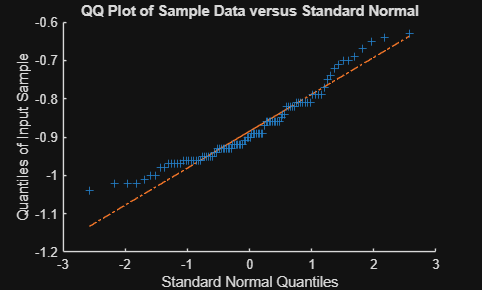

figure(3)
qqplot(difference)

The quantile plot shows that `difference` has a lighter left tail and heavier right tail than the Normal distribution, and so is not Normally distributed. However, our data set is sufficiently large to assume that $\overline{D}\sim N\left(\mu_{x} - \mu_{y}, n^{-1/2}\sigma \right)$, where $\sigma = \sqrt{\sigma^{2}_{x} + \sigma^{2}_{y}}$. So we have a single independent sample for which the sample mean is Normally distributed—we can use the t-test for means! Additionally, 


$$\left[\overline{D} \pm t_{n - 1, 1 - \alpha / 2} \frac{D_{d}}{\sqrt{n}}\right]$$


is the $100(1 - \alpha)\%$ confidence interval for $\mu_{d}$.  

alpha = 0.05; %you can change the significance level
[~, p, ci, stats] = ttest(difference); % ttest(difference, "Alpha", alpha)

p

p = 1.3146e-99

ci

ci =    -0.8989
   -0.8625


stats

stats = struct with fields:
    tstat: -96.2166
       df: 99
       sd: 0.0915


 Our p-valued $p\approx 10^{-99} \approx 0$. Hence we have very strong (effectively insurmountable) evidence that $\mu_{D} \neq 0$. Equivalently, we have very strong evidence that the location of the sensors affects their readings. This is corroborated by the 95% confidence interval for $\mu_{D}$: $[-0.8989, -0.8625]$, which does not contain 0. 